f = @(x) (2*x.^3 + 3*x - 1).*cos(x) - x;
a = -1; b = 1;
tol = 1e-5; N = 100;
[c,n,err]=  bisection_method1(f,a,b,tol,N)

c = 0.4386

n = 17

err = 7.6294e-06

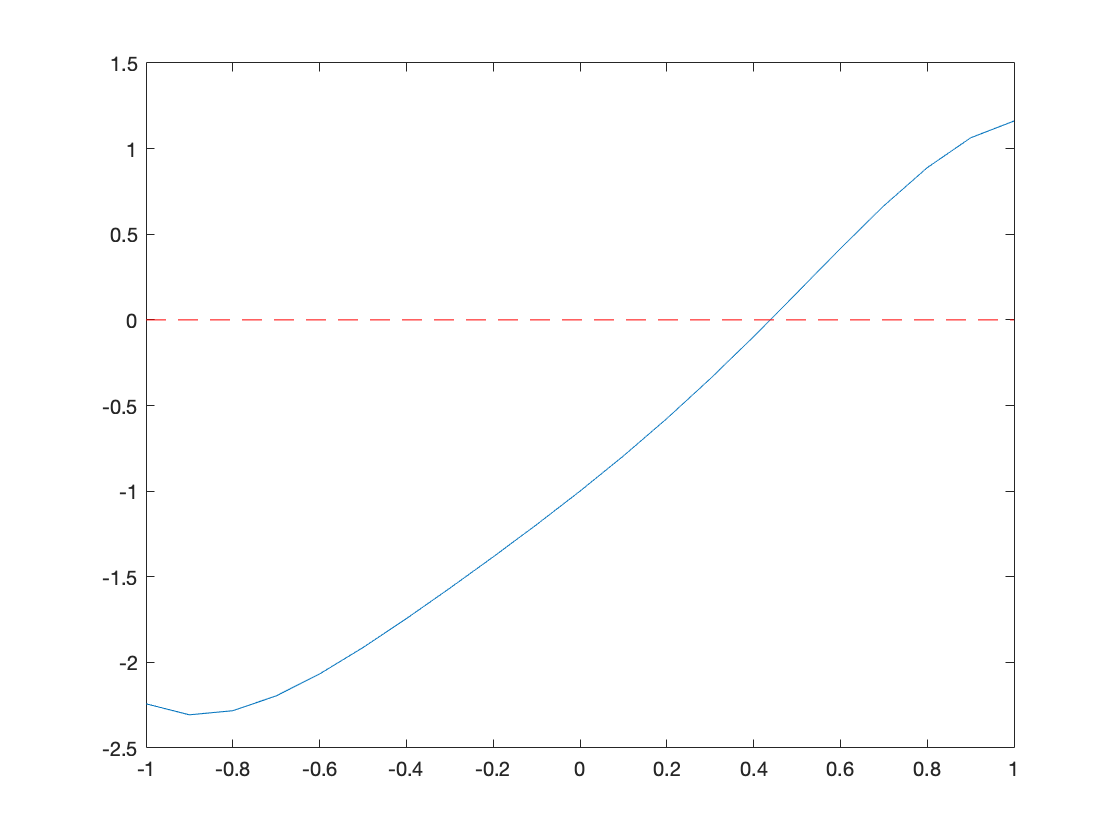

plot([-1:0.1:1],f([-1:0.1:1]),[-1:0.1:1],0*[-1:0.1:1], 'r--')



f1 = @(x) (x.^4);
a1 = -1;
b1 = 2;
tol1 = 1e-5; N1 = 100;
[c1, n1, err1] = bisection_method1(f1, a1, b1, tol1, N1)

c1 = 2.0000

n1 = 18

err1 = 5.7220e-06

function[c, n, err] = bisection_method1(f, a, b, tol, N)  
n = 0;
c = (a + b) / 2;
err = (b-a)/2;

while err > tol && n < N
    
if f(a) * f(c) < 0
        b = c;
        
else
        a = c;
        
end
    
    c = (a + b) / 2;
    err = (b-a)/2;
    n = n + 1;
end
end
